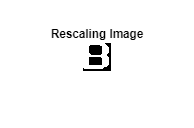

clc; clear; close all; % Clear console, variables, and figures
size = 28; % Define image size
fileID = fopen('input_bram_to_cnn_image.mem', 'rt');
data = textscan(fileID, '%s');
fclose(fileID);
binary_img = strcmp(data{1}, '1'); % Convert '1' to 1 (white), others to 0 (black)
img = reshape(binary_img, size, size)'; % Reshape and transpose to form image matrix
imshow(img, []); title('Rescaling Image'); % Display the image

resized_img = imresize(img, [size, size]); % Resize image (same size in this case)

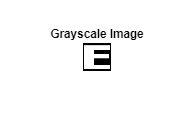

% Step 1: Read the image
img = imread('class_E_3.jpg');
clear size
% Step 2: Convert to grayscale if it's RGB
if size(img, 3) == 3
    img_gray = rgb2gray(img);
else
    img_gray = img;
end

% Step 3: Convert to double and normalize (optional, range 0 to 1)
img = double(img_gray) / 255;
% Step 4: Display and verify
imshow(img, []);
title('Grayscale Image');

%layer 1 conv

filter_values_1 = squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d/vars/0'));


bias_1=squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d/vars/1'));


conv_result = conv2(img, filter_values_1, 'same')+bias_1;

conv_clipped = max(conv_result, 0);
% Display the result
imshow(conv_clipped, []);
conv_clipped

conv_clipped = 28×28 single matrix
    0.0700    0.0713    0.0771    0.0784    0.0829    0.0804    0.0714    0.0735    0.0760    0.0759    0.0752    0.0709    0.0947    0.0916    0.0744    0.0734    0.0709    0.0709    0.0709    0.0709    0.0709    0.0709    0.0709    0.0709    0.0706    0.0815    0.0766    0.0700
    0.0502    0.8275    1.3834    1.3799    1.3899    1.4059    1.3955    1.3922    1.3926    1.3942    1.4005    1.3800    1.3669    1.3948    1.3871    1.3936    1.3986    1.3986    1.3986    1.3986    1.3986    1.3986    1.3986    1.3988    1.3852    1.3947    1.4128    0.6363
         0    0.3045    1.5707    1.5440    1.5508    1.5409    1.5626    1.5645    1.5504    1.5610    1.5569    1.5601    1.5593    1.5322    1.5697    1.5533    1.5655    1.5681    1.5681    1.5681    1.5681    1.5681    1.5681    1.5722    1.5631    1.5494    2.0249    1.3341
         0         0    0.2942    0.3140    0.2971    0.2976    0.3071    0.2992    0.3030    0.2886    0.3095    0.3174  

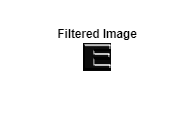

title('Filtered Image');

%max pool layer1
size=28;
% Define pooling window size
pool_size = 2;
% Initialize output size
pooled_output_1 = zeros(floor(size/pool_size), floor(size/pool_size));

% Perform 2x2 max pooling
for i = 1:pool_size:size-pool_size+1
    for j = 1:pool_size:size-pool_size+1
        block = conv_clipped(i:i+1, j:j+1);
        pooled_output_1((i+1)/2, (j+1)/2) = max(block(:));
    end
end

% Display the input and pooled result
imshow(pooled_output_1, []);
pooled_output_1

pooled_output_1 =     0.8275    1.3834    1.4059    1.3955    1.3942    1.4005    1.3948    1.3936    1.3986    1.3986    1.3986    1.3988    1.3947    1.4128
    0.3045    1.5707    1.5508    1.5645    1.5610    1.5601    1.5593    1.5697    1.5681    1.5681    1.5681    1.5722    1.5631    2.0249
         0    0.1109    0.1161    0.1046    0.1182    0.1018    0.1142    0.1149    0.1028    0.1028    0.1028    0.1069    0.1129    1.0907
         0    0.1097    0.1151    0.1140    0.1043    0.6453         0         0         0         0         0         0         0         0
         0    0.1045    0.1058    0.1049    0.1077    1.0869    0.0771    0.0882    0.0734    0.0709    0.0709    0.0709    0.0764    0.0777
         0    0.1028    0.1028    0.1049    0.1066    1.5277    1.6013    1.6003    1.6126    1.6098    1.6098    1.6098    2.0991    1.4241
         0    0.1028    0.1028    0.1090    0.1058    0.1037    0.1111    0.1097    0.1092    0.1028    0.1028    0.1063    1.0822    0.

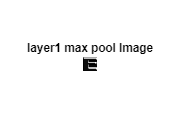

title('layer1 max pool Image');

filter_values_2 = squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d_1/vars/0'));

bias_2=squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d_1/vars/1'));
conv_result_2 = conv2(pooled_output_1, filter_values_2, 'same')+bias_2;
conv_clipped_2 = max(conv_result_2, 0);
% Display the result
imshow(conv_clipped_2, []);
conv_clipped_2

conv_clipped_2 = 14×14 single matrix
    1.6451    0.7412         0         0         0         0         0         0         0         0         0         0    0.1138         0
    1.7557    3.6582    3.6708    3.7078    3.6765    3.6909    3.7004    3.6832    3.6875    3.7000    3.7046    3.7025    4.4725    2.5233
    0.1507    1.9164    3.2220    3.2086    3.5087    2.9040    2.9617    3.2776    3.2820    3.2856    3.2879    3.2985    3.8498    4.2523
         0    0.0272    0.0586    0.0432    0.8764         0         0         0         0         0         0         0         0    1.0646
         0    0.0174    0.0508    0.0569    1.3363    1.1338         0         0         0         0         0         0         0         0
         0    0.0095    0.0366    0.0342    0.8214    2.6464    2.0037    0.8372    0.8352    0.8120    0.8153    1.6151    0.7236         0
         0    0.0079    0.0333    0.0384    0.1468    1.2677    3.0254    3.3596    3.3690    3.3773    3.3792    3.9

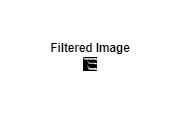

title('Filtered Image');

%max pool layer2
size=14;
% Define pooling window size
pool_size = 2;
% Initialize output size
pooled_output2 = zeros(floor(size/pool_size), floor(size/pool_size));

% Perform 2x2 max pooling
for i = 1:pool_size:size-pool_size+1
    for j = 1:pool_size:size-pool_size+1
        block = conv_clipped_2(i:i+1, j:j+1);
        pooled_output2((i+1)/2, (j+1)/2) = max(block(:));
    end
end

% Display the input and pooled result
imshow(pooled_output2, []);
pooled_output2

pooled_output2 =     3.6582    3.7078    3.6909    3.7004    3.7000    3.7046    4.4725
    1.9164    3.2220    3.5087    3.2776    3.2856    3.2985    4.2523
    0.0174    0.0569    2.6464    2.0037    0.8352    1.6151    0.7236
    0.0079    0.0428    1.2677    3.3596    3.3773    3.9339    4.7792
    0.0079    0.0401    1.6094         0         0         0         0
    0.0139    0.0349    3.0565    4.4038    4.1595    4.1634    4.9840
         0    0.0513    0.7172    3.2263    3.2387    3.2442    4.2622


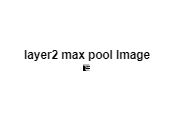

title('layer2 max pool Image');

filter_values_3 = squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d_2/vars/0'));

bias_3=squeeze(h5read('my_checkpoint.weights.h5', '/layers/conv2d_2/vars/1'));
conv_result3 = conv2(pooled_output2, filter_values_3, 'same')+bias_3;
conv_clipped3 = max(conv_result3, 0);
% Display the result
imshow(conv_clipped3, []);
conv_clipped3

conv_clipped3 = 7×7 single matrix
    4.1965    4.4496    4.6436    4.4515    4.4664    4.9961    2.7589
    9.5786   13.4823   15.2323   14.5997   13.7149   15.5552   10.3563
    4.3690   10.3110   12.6627   12.8858   13.1661   13.8117   12.8175
         0    2.2736    8.5494    8.3869    6.5341    6.5144    2.1884
         0    1.6362    5.9611   10.7990   13.4882   14.7588   14.6610
         0    2.9808    5.9862    6.7670    4.6675    5.2747    2.7243
         0    2.1090    9.0410   14.1812   14.8102   15.7588   11.0553


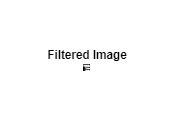

title('Filtered Image');

%max pool layer3
size=7;
% Define pooling window size
pool_size = 2;
% Initialize output size
pooled_output3 = zeros(floor(size/pool_size), floor(size/pool_size));

% Perform 2x2 max pooling
for i = 1:pool_size:size-pool_size+1
    for j = 1:pool_size:size-pool_size+1
        block = conv_clipped3(i:i+1, j:j+1);
        pooled_output3((i+1)/2, (j+1)/2) = max(block(:));
    end
end

% Display the input and pooled result
imshow(pooled_output3, []);
pooled_output3

pooled_output3 =    13.4823   15.2323   15.5552
   10.3110   12.8858   13.8117
    2.9808   10.7990   14.7588


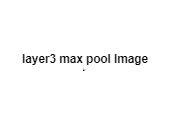

title('layer3 max pool Image');

% Step 1: Read the file into a vector

flattened_9x1 = reshape(pooled_output3', [], 1)

flattened_9x1 =    13.4823
   15.2323
   15.5552
   10.3110
   12.8858
   13.8117
    2.9808
   10.7990
   14.7588


%weights = load('dense_weights.mem');  % assumes decimal values line-by-line
% Step 2: Check if the number of values is correct
% if numel(weights) ~= 9*18
%     error('Expected 162 values to form a 9x18 matrix.');
% end
% Step 3: Reshape the vector into a 9x18 matrix
% dense_matrix = reshape(weights, [18,9])';  % Transpose for 9 rows, 18 cols
% 
% Step 4: Display or use the matrix
% disp('Dense Weight Matrix (9x18):');
% disp(dense_matrix);
%h5disp('my_checkpoint.weights.h5');
dense_weights_1 = h5read('my_checkpoint.weights.h5', '/layers/dense/vars/0');  % size: 18x9


% Step 3: Reshape the vector into a 9x18 matrix
bias_matrix = h5read('my_checkpoint.weights.h5', '/layers/dense/vars/1')  % Transpose for 9 rows, 18 cols

bias_matrix = 18×1 single column vector
   -0.6004
   -0.0384
   -0.3667
   -0.1902
   -0.0162
   -0.0208
   -0.1619
    0.2708
   -0.0368
    0.7120



% Step 4: Display or use the matrix

disp(bias_matrix);

   -0.6004
   -0.0384
   -0.3667
   -0.1902
   -0.0162
   -0.0208
   -0.1619
    0.2708
   -0.0368
    0.7120
   -0.0459
    0.0855
    0.9260
   -0.2171
   -0.1170
   -0.3256
    0.5689
   -0.0898




final_1 = max((dense_weights_1*flattened_9x1)+bias_matrix,0)

final_1 = 18×1 single column vector
   10.1808
   12.4250
    8.4635
    8.7583
         0
    9.2858
    2.3979
         0
    0.0917
    7.1841



dense_weights_2 = h5read('my_checkpoint.weights.h5', '/layers/dense_1/vars/0');  % 36x18

bias = load('dense_1_biases.mem');  % assumes decimal values line-by-line
% Step 2: Check if the number of values is correct
if numel(bias) ~= 1*36
    error('Expected 36 values to form a 1x36 matrix.');
end
% Step 3: Reshape the vector into a 9x18 matrix
bias_matrix_2 = h5read('my_checkpoint.weights.h5', '/layers/dense_1/vars/1');  % Transpose for 9 rows, 18 cols

% Step 4: Display or use the matrix

disp(bias_matrix_2);

   -0.1561
    0.3990
    0.2110
    0.0931
    0.2165
    0.0951
   -0.1445
    0.7403
   -0.0486
   -0.1131
   -0.4854
   -0.1550
   -0.0569
   -0.0056
    0.0174
    0.2232
   -0.1872
   -0.0166
    0.1710
    0.4075
   -0.1615
   -0.0267
   -0.4700
   -0.5417
   -0.1733
    0.0108
   -0.1234
   -0.4106
    0.0167
    0.0998
   -0.0092
   -0.2738
   -0.4661
   -0.2124
   -0.1687
    0.6939




final_2 = (dense_weights_2*final_1)+bias_matrix_2

final_2 = 36×1 single column vector
  -35.7916
   -8.3431
   -9.8240
  -13.9295
  -12.8417
  -11.2126
  -28.3051
  -18.0293
  -11.2484
  -14.7384


softmax_output = exp(final_2) / sum(exp(final_2))

softmax_output = 36×1 single column vector
    0.0000
    0.1930
    0.0439
    0.0007
    0.0021
    0.0110
    0.0000
    0.0000
    0.0106
    0.0003


labels = ['0':'9', 'A':'Z'];  % Total 36 classes

% Get indices of Top 3 values (sorted descending)
[sorted_probs, sorted_indices] = sort(softmax_output, 'descend');
top3_indices = sorted_indices(1:3);
top3_probs = sorted_probs(1:3);
top3_labels = labels(top3_indices);

% Display Top-3 results
fprintf('Top 3 Predicted Labels:\n');

Top 3 Predicted Labels:


for i = 1:3
    fprintf('%d. Label: %s | Probability: %.4f\n', i, top3_labels(i), top3_probs(i));
end

1. Label: R | Probability: 0.4205
2. Label: S | Probability: 0.2027
3. Label: 1 | Probability: 0.1930
